# Informe Laboratorio: Análisis Numérico

# Práctica No. 10: Differential Equations

**Juan Pablo Jiménez Gómez **

**Código: 2173051**

**Grupo: B2**

*Escuela de ingeniería de sistemas e informática*

*Universidad Industrial de Santander*

5 de Febrero del 2021

### 3 Practice 

### 3.1 Understanding 

Answer with your own words the following questions: 

-  (0.2 points) How to solve a differential equation with initial value by using Euler’s method? 

Comenzamos con un problema de valor inicial (PVI) general de primer orden.


$$\frac{\textrm{dy}}{\textrm{dt}}=f\left(t,y\left(t\right)\right),y\left(t_0 \right)=y_0$$


Donde 𝑓(𝑡,𝑦(𝑡)) es una función conocidad y los valores en la condición incial tambien son numeros conocidos. A partir del segundo teorema de existencia y unicidad, sabemos que si 𝑓 y 𝑓𝑦 son funciones constinuas, entonces hay una solución única para el PVI en algún intervalo que rodea 𝑡0≤𝑡≤𝑡0+𝛿


$$\int_{t_0 }^{t_1 } y^{\prime } \left(t\right)\textrm{dt}=\int_{t_0 }^{t_1 } y^{\prime } \left(t\right)\textrm{dt}=$$


𝑦1−𝑦0≈(𝑡1−𝑡0)𝑓(𝑡0,𝑦0)

𝑦1≈𝑦0+(𝑡1−𝑡0)𝑓(𝑡0,𝑦0)

𝑦𝑘+1≈𝑦𝑘+ℎ𝑓(𝑡𝑘,𝑦𝑘)

𝑡𝑘+1=𝑡𝑘+ℎ

Ya que el metodo de euler es iterativo lo que tendremos que hacer es remplazar los valores correspondiente al valor anterior a la solución dada, empezando por los valores inicial propuesto de la función

-  (0.2 points) How to solve a differential equation with initial value by using Heun’s method?  

- (0.2 points) How to solve a differential equation with initial value by using forth-order RungeKutta method? 

-  (0.2 points) What applications do the differential equations have? 

### 3.2 Applying

- (1.2 points) Solve the diferential equation using the forth-order Runge-Kutta method (RK4).

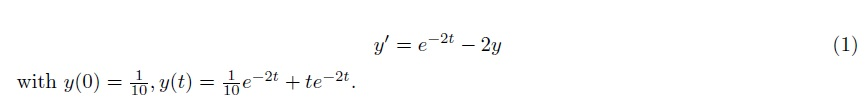

- Take h = 0:2 and take two steps calculating the values. Then, take h = 0:1 and take four steps calculating the values.

First we use the RK4 method to resolve the exercise We take h = 0.2 to calculate the values. x = [0, 0.2, 0.4]

we assign the origin value $y\left(0\right)=\frac{1}{10}$

After this we calculate the k values for the first iteration


$$\begin{array}{l}
k_1 =0\ldotp 2\left(0\ldotp 8\right)=0\ldotp 16\\
k_2 =0\ldotp 2\left(0\ldotp 45873\right)=0\ldotp 091746\\
k_3 =0\ldotp 2\left(0\ldotp 52698\right)=0\ldotp 1054\\
k_4 =0\ldotp 2\left(0\ldotp 25953\right)=0\ldotp 051905
\end{array}$$


Now we have the values of K, with this we can already obtain the value y1


$$y_1 =y_0 +\frac{1}{6}*\;\left(k_1 +2k_2 +2k_3 +k_4 \right)=0\ldotp 20103$$


Now we do a new iteration where we calculate the new values for K


$$\begin{array}{l}
k_1 =0\ldotp 2\left(0\ldotp 26826\right)=0\ldotp 053651\\
k_2 =0\ldotp 2\left(0\ldotp 093097\right)=0\ldotp 018619\\
k_3 =0\ldotp 2\left(0\ldotp 12813\right)=0\ldotp 025626\\
k_4 =0\ldotp 2\left(-0\ldotp 0039862\right)=-0\ldotp 00079725
\end{array}$$


We calculate the respective approximation y(0.4)


$$y_2 =y_1 +\frac{1}{6}*\;\left(k_1 +2k_2 +2k_3 +k_4 \right)=0\ldotp 22459$$


Second  we take h=0.1 and the calculate the values x = [0, 0.1, 0,2, 0.3, 0.4]

we assign the origin value $y\left(0\right)=\frac{1}{10}$

After this we calculate the k values for the first iteration


$$\begin{array}{l}
k_1 =0\ldotp 1\left(0\ldotp 8\right)=0\ldotp 08\\
k_2 =0\ldotp 1\left(0\ldotp 62484\right)=0\ldotp 062484\\
k_3 =0\ldotp 1\left(0\ldotp 64235\right)=0\ldotp 064235\\
k_4 =0\ldotp 1\left(0\ldotp 49026\right)=0\ldotp 049026
\end{array}$$


Now we have the values of K, with this we can already obtain the value y1


$$y_1 =y_0 +\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)=0\ldotp 16374$$


Now we do a new iteration where we calculate the new values for K


$$\begin{array}{l}
k_1 =0\ldotp 1\left(0\ldotp 49124\right)=0\ldotp 049124\\
k_2 =0\ldotp 1\left(0\ldotp 36421\right)=0\ldotp 036421\\
k_3 =0\ldotp 1\left(0\ldotp 37691\right)=0\ldotp 037691\\
k_4 =0\ldotp 1\left(0\ldotp 26745\right)=0\ldotp 026745
\end{array}$$


We calculate the respective approximation y2


$$y_2 =y_1 +\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)=0\ldotp 20109$$


Now we iniciate the next iteration and calculate the new values of K


$$\begin{array}{l}
k_1 =0\ldotp 1\left(0\ldotp 26813\right)=0\ldotp 026813\\
k_2 =0\ldotp 1\left(0\ldotp 17753\right)=0\ldotp 017753\\
k_3 =0\ldotp 1\left(0\ldotp 18659\right)=0\ldotp 018659\\
k_4 =0\ldotp 1\left(0\ldotp 10931\right)=0\ldotp 010931
\end{array}$$


If we have the values of K, we can determinate the values of y3


$$y_3 =y_2 \;+\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)=0\ldotp 21952$$


Then we do the last iteratión 


$$\begin{array}{l}
k_1 =0\ldotp 1\left(0\ldotp 10977\right)=0\ldotp 026813\\
k_2 =0\ldotp 1\left(0\ldotp 046566\right)=0\ldotp 017753\\
k_3 =0\ldotp 1\left(0\ldotp 052887\right)=0\ldotp 018659\\
k_4 =0\ldotp 1\left(-0\ldotp 00029024\right)=2\ldotp 9024e^{-0\ldotp 5} 
\end{array}$$


And finally we calculate the aproximation for y(0.4)


$$y_4 =y_3 \;+\frac{1}{6}\left(k_1 +2k_2 +2k_3 +k_4 \right)=0\ldotp 22466$$


-  Compare the exact solution y(0:4) with the two approximations calculated in the previous point.

#### 
$$y\left(0\ldotp 4\right)=\frac{1}{10}e^{\left(-2\left(0\ldotp 4\right)\right)} +\left(0\ldotp 4\right)e^{\left(-2\left(0\ldotp 4\right)\right)} =0\ldotp 22466$$


- ** Does the �nal global error of the approximations obtained in the previous points behave, as expected when h is divided between two?**

For the value of h=0.2


$$\textrm{Relative}\_\textrm{Error}=\frac{\left(0\ldotp 22466-0\ldotp 22459\right)}{0\ldotp 22466}=0\ldotp 00031$$


For the value h=0.1


$$\textrm{Relative}\_\textrm{Error}=\frac{\left(0\ldotp 22466-0\ldotp 22466\right)}{0\ldotp 22466}=0$$


the smaller the value of h, the better the approximation.

- **(1.2 points) Let M(t) be the amount of a product that decreases with time t and the rate of decrease is proportional to the amount M.**

**1)  Determine a diferential equation that models the phenomena.**


$$\frac{\textrm{dM}}{\textrm{dt}}=-t*M\;\textrm{is}\;\textrm{equivalent}\;\textrm{to}\;\textrm{have}\;\frac{\textrm{dM}}{\textrm{dt}}=-M\;$$


**2) Solve the diferential equation to determine the amount of material at time t = 1. Use the Euler method with a step of h = 0:2. Consider that M(0) = 300.**

Your input: find y(1) for y′=−y, when y(0)=300,h=$\frac{1}{5}$ using the 

 
$$t_1 =t_0 +h=0+\frac{1}{5}=\frac{1}{5}$$


$y_1$=$y_0 +h*f\left(t_0 ,y_0 \right)=300+h*f\left(0,300\right)$

**3)  Solve the diferential equation to determine the amount of material at time t = 1. Use the Heun method with a step of h = 0:2. Consider that M(0) = 300.**

 We obtain the time intervals, knowing that h = 0.2, we have that t = [0, 0.2, 0.4, 0.6, 0.8, 1].

We will proceed to make the respective iterations up to y5


$$\begin{array}{l}
y_1 =300+0\ldotp 2\left(300\right)=240\\
y_2 =240+0\ldotp 2\left(-240\right)=192\\
y_3 =192+0\ldotp 2\left(-192\right)=153\ldotp 6\\
y_4 =153\ldotp 6+0\ldotp 2\left(-153\ldotp 6\right)=122\ldotp 88\\
y_5 =122\ldotp 88+0\ldotp 2\left(-122\ldotp 88\right)=98\ldotp 304
\end{array}$$


When we evaluate the function when t=1 we have that y(t) = 98.304 

### 3.3 Implementing

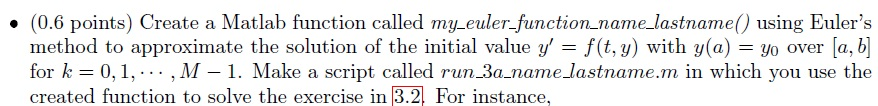

close all;
clear;
k=1;
a=0;
b=1;
ya=300;
M=5;
f= @(t,m) -m;
E = my_euler_function_Juan_Jimenez(f,a,b,ya,M);
disp(E);

         0  300.0000
    0.2000  240.0000
    0.4000  192.0000
    0.6000  153.6000
    0.8000  122.8800
    1.0000   98.3040



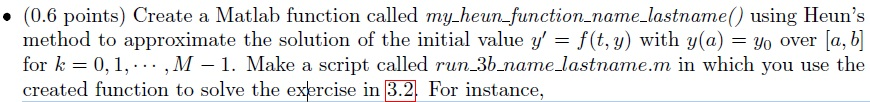

k=1;
a=0;
b=1;
ya=300;
M=5;
f= @(t,m) -m;
H = my_heun_function_Juan_Jimenez(f,a,b,ya,M);

disp(H);

         0  300.0000
    0.2000  246.0000
    0.4000  201.7200
    0.6000  165.4104
    0.8000  135.6365
    1.0000  111.2220



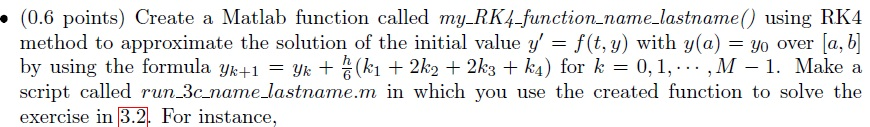

a = 0;
b = 1;
ya = 300;
M = 5;
f = @(t,m) -m;
R=my_RK4_function_Juan_Jimenez(f,a,b,ya,M);
disp(R);

         0  300.0000
    0.2000  245.6200
    0.4000  201.0973
    0.6000  164.6450
    0.8000  134.8004
    1.0000  110.3656



### ANEXES

**The functions below were taken from the matlab method book**

**my_euler_*****function_Juan_Jimenez*****()**

function E= my_euler_function_Juan_Jimenez(f,a,b,ya,M)
h=(b-a)/M;
T=zeros(1,M+1);
Y=zeros(1,M+1);
T=a:h:b;
Y(1)=ya;
for j=1:M
    Y(j+1)=Y(j)+h*feval(f,T(j),Y(j));
end
E=[T' Y'];
end

**my_heun_*****function_Juan_Jimenez*****()**

function H= my_heun_function_Juan_Jimenez(f,a,b,ya,M)
h=(b-a)/M;
T=zeros(1,M+1);
Y=zeros(1,M+1);
T=a:h:b;
Y(1)=ya;
for j=1:M
    k1=feval(f,T(j),Y(j));
    k2=feval(f,T(j+1),Y(j)+h*k1);
    Y(j+1)=Y(j)+(h/2)*(k1+k2);
end
H=[T' Y'];
end

**my_RK4_*****function_Juan_Jimenez*****()**

function R=my_RK4_function_Juan_Jimenez(f,a,b,ya,M)
h=(b-a)/M;
T=zeros(1,M+1);
Y=zeros(1,M+1);
T=a:h:b;
Y(1)=ya;
for j=1:M
    k1=h*feval(f,T(j),Y(j));
    k2=h*feval(f,T(j)+h/2,Y(j)+k1/2);
    k3=h*feval(f,T(j)+h/2,Y(j)+k2/2);
    k4=h*feval(f,T(j)+h,Y(j)+k3);
    Y(j+1)=Y(j)+(k1+2*k2+2*k3+k4)/6;
end
R=[T' Y'];
end

